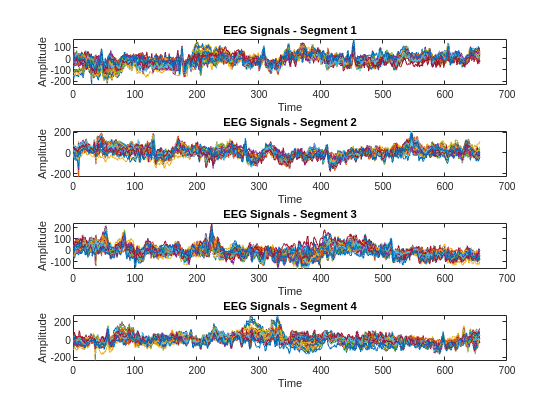

num_segments = min(numel(t1s), 4); 

figure;
for i = 1:num_segments
    subplot(num_segments, 1, i);
    plot(t1s{i}');
    title(['EEG Signals - Segment ', num2str(i)]);
    xlabel('Time');
    ylabel('Amplitude');
end

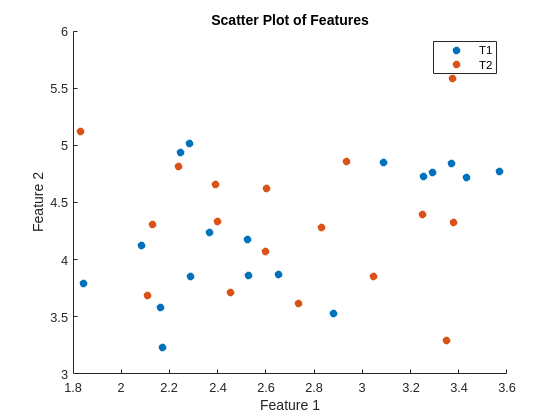

data = load('featureVectors.txt');

feature1 = data(:, 1);
feature2 = data(:, 2);
classLabels = importdata('referenceClass.txt');

T1_indices = find(strcmp(classLabels, 'T1'));
T2_indices = find(strcmp(classLabels, 'T2'));

figure;
scatter(feature1(T1_indices), feature2(T1_indices), 'filled', 'DisplayName', 'T1');
hold on;
scatter(feature1(T2_indices), feature2(T2_indices), 'filled', 'DisplayName', 'T2');
title('Scatter Plot of Features');
xlabel('Feature 1');
ylabel('Feature 2');
legend('show');